# Sin Function Test

## Clear Workspace

close all; clearvars; clc;

## Vars

sample_HZ = 1e6; % HZ
timeStep = 1/sample_HZ;
A = 1; % amplitude p-pk V
f1 = 10e3;
T1 = 1/f1;
f2 = 30e3;
f3 = 50e3;
periods = 1/eval(gcd(sym([f1 f2 f3])));
t = (0:timeStep:periods-timeStep)';

## Function

y = A*sin(2*pi*f1*t) + A*sin(2*pi*f2*t) + A*sin(2*pi*f3*t);
numCycles = ceil(500e3/(periods/timeStep));
sine = repmat(y, numCycles, 1);

## Plot Figures

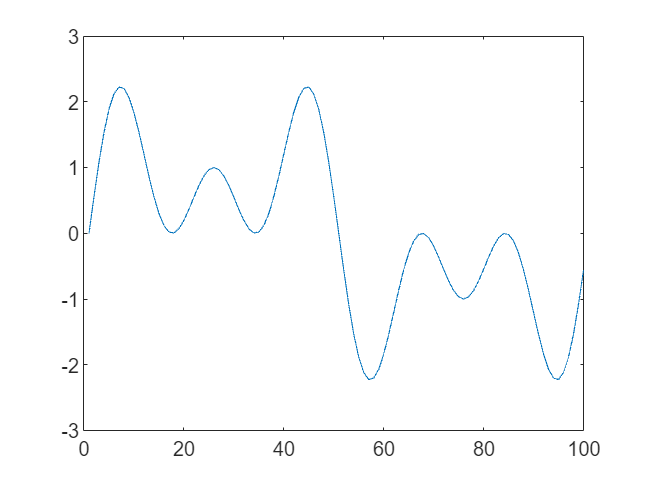

figure
plot(y)

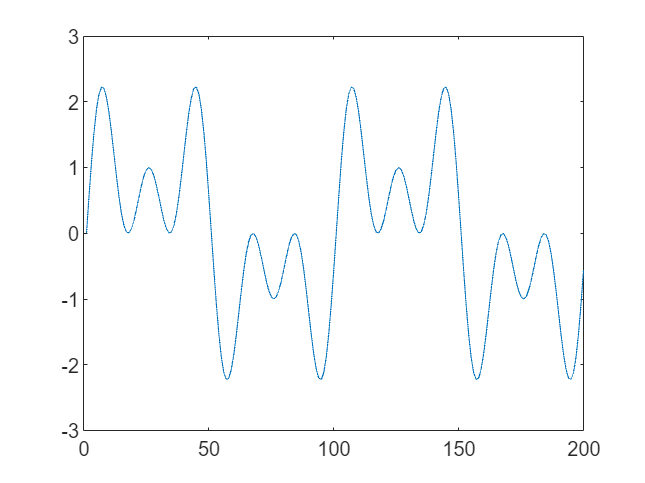


figure
plot(sine)
xlim([0 (periods/timeStep)*2])